# 4.5 Check the controllability and observability properties of the linearized system

First let's check controllability

load Linear_Param.mat
B1 = B(:,1);
format shortE
Cont = [B1, A*B1, A^2*B1,A^3*B1]

Cont =             0   2.0576e+01  -9.7737e+03   4.6431e+06
   2.0576e+01  -9.7737e+03   4.6431e+06  -2.2058e+09
            0  -9.0028e+01   4.2764e+04  -2.0319e+07
  -9.0028e+01   4.2764e+04  -2.0319e+07   9.6527e+09


rank(Cont)

ans =      4


det(Cont)

ans =    4.2840e+09


The system is fully controllable. 

Observability

C = [0 0 1 0];
Obsv = [C;C*A;C*A^2;C*A^3]

Obsv =             0            0   1.0000e+00            0
            0            0            0   1.0000e+00
            0   1.9034e+03   6.2019e+01  -3.9972e+01
            0  -9.0415e+05  -1.4088e+04   1.9049e+04


rank(Obsv)

ans =      3


det(Obsv)

ans =      0


System is not observable when only the body angle is observed. This is because we cannot determine the position of the wheel if we only know the body angle. Simply adding the wheel position to the output gives:

C = [0 1 1 1];
Obsv = [C;C*A;C*A^2;C*A^3]

Obsv =             0   1.0000e+00   1.0000e+00   1.0000e+00
            0   1.4684e+03   5.5920e+01  -2.9837e+01
            0  -6.9560e+05  -1.0806e+04   1.4663e+04
            0   3.3052e+08   5.1519e+06  -6.9517e+06


rank(Obsv)

ans =      3


det(Obsv)

ans =      0


Now the observability matrix is full rank. The consequences of this is that the transfer function becomes

[NUM,DEN] = ss2tf(A,B1,C,0);
sys = tf(NUM,DEN)

sys =
 
      -69.45 s^3 - 90.03 s^2 - 727 s
  --------------------------------------
  s^4 + 475 s^3 - 62.02 s^2 - 1.537e04 s
 
Continuous-time transfer function.
Model Properties


poles = pole(sys)

poles =             0
  -4.7507e+02
   5.7195e+00
  -5.6571e+00


zeros = zero(sys)

zeros =    0.0000e+00 + 0.0000e+00i
  -6.4813e-01 + 3.1698e+00i
  -6.4813e-01 - 3.1698e+00i


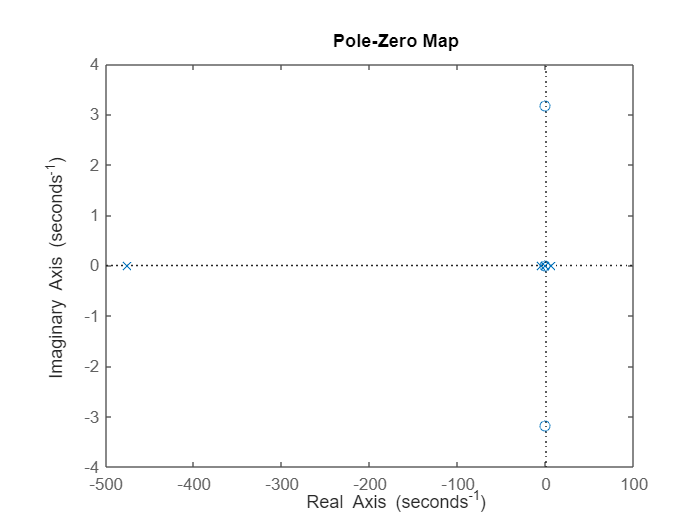

pzmap(sys)

The poles are still the same, though there is no longer a pole/zero cancellation at s=0 meaning that the system is now fourth order. The zeros are now mostly complex conjugates.